# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

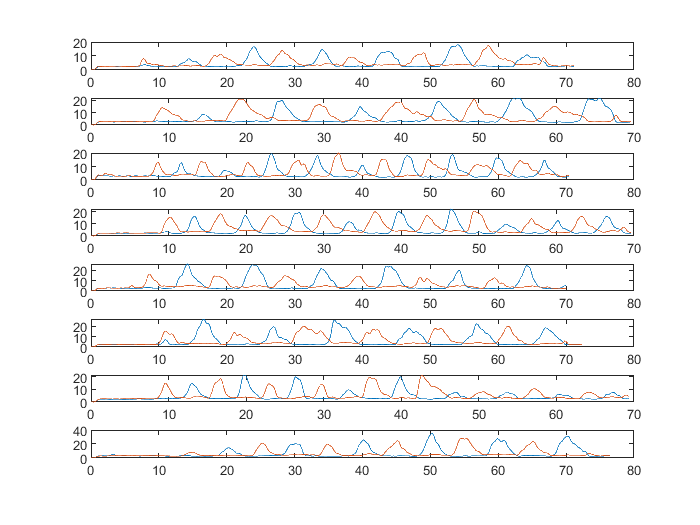

%uso della funzione get_envelope() 

fs = 2000;
nfft= 2048;

[inviluppo, T] = get_envelope (emg_data, fs);
for index = 1 : 8
subplot(8,1,index)
tempo = cell2mat(T(index,3));
dato = cell2mat(inviluppo(index,3));
plot(tempo,dato)
end

*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

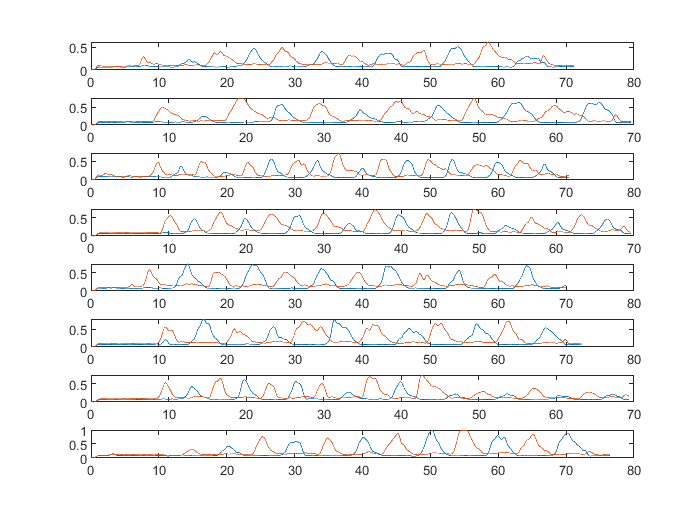

%uso funzione data_normalization()
signal = cell2mat(emg_data(1, 1));
time = signal(:,1);
norm=data_normalization(inviluppo);

% for index = 1 : 8
% subplot(8,1,index)
% tempo = cell2mat(T(index,3));
% dato = cell2mat(norm(index,3));
% plot(tempo,dato)
% end

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

% % f = linspace (0, fs/2, floor(nfft/2)+1);
% overlap=100;
% window=200;
% % 
% % %utilizzo funzione meanpsd() per il calcolo e la visualizzazione dello
% % %spettro di potenza medio di ciascun muscolo di ogni soggetto
% meanpsd(norm,overlap,window,1024,fs)

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

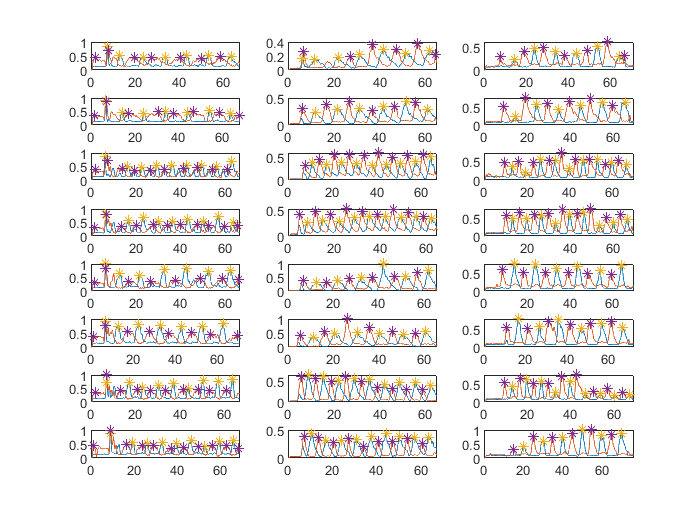

%uso funzione detect_activation()
[num_casi, num_soggetti] = size(norm);

[peaks,time_peaks]=detect_activation(norm, T, 0.25);  

for index_soggetto = 1 : num_soggetti
for index_caso = 1 : num_casi
subplot(num_casi, num_soggetti, index_soggetto+(index_caso-1)*3)

tempo = cell2mat(T(index_caso,index_soggetto));
dato = cell2mat(norm(index_caso,index_soggetto));
plot(tempo,dato)
hold on

tempo_picco1= cell2mat(time_peaks(index_caso,2*index_soggetto-1));
picco1 = cell2mat(peaks(index_caso,2*index_soggetto-1));

plot(tempo(tempo_picco1),picco1,'*')

hold on

tempo_picco2= cell2mat(time_peaks(index_caso,2*index_soggetto));
picco2 = cell2mat(peaks(index_caso,2*index_soggetto));

plot(tempo(tempo_picco2),picco2,'*')

hold off
end
end

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

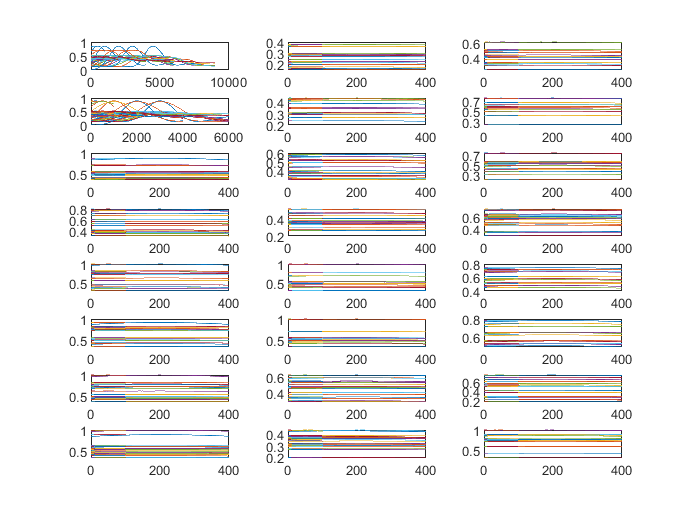

Index in position 1 exceeds array bounds (must not exceed 136732).

single_peaks=cell(num_casi, num_soggetti);
M=1000;

for index_soggetto = 1 : num_soggetti
for index_caso = 1 : num_casi
    
    tempo_picco1= cell2mat(time_peaks(index_caso,2*index_soggetto-1));
    tempo_picco2= cell2mat(time_peaks(index_caso,2*index_soggetto));
    dato = cell2mat(norm(index_caso,index_soggetto));
    
    subplot(num_casi, num_soggetti, index_soggetto+(index_caso-1)*3)
    
    for index_picco2 = 1 : length (tempo_picco2)
    singolo_picco2 = dato(tempo_picco2(index_picco2)-(M/2): tempo_picco2(index_picco2)+(M/2),2 ) ;
    plot(singolo_picco2)
    hold on
    end
    
%     single_peaks{index_caso, index_soggetto} = [singolo_picco1 , singolo_picco2];

end
end

% 
% %numero finestre è il numero di picchi
% [casi, sei]=size(time_peaks);
% N=zeros(casi,sei);
% distanza=zeros(casi, sei);
% 
% 
% for index_sei=1:sei
% for index_casi=1:casi
%         N(index_casi, index_sei)=length(cell2mat(peaks(index_casi, index_sei)));
%         differenza= diff(cell2mat(time_peaks (index_casi, index_sei)));
%         distanza (index_casi, index_sei)=min (differenza);
% end
% end
% 
% %lunghezza della finestra
% M=floor(min(distanza,[], 'all'));
% 
% M=M/3;
% 
% %asse x, potrebbero essere gli indici
% %ma per assex vorrei il tempo non gli indici
% %inutile
% axes=linspace(-M/2,M/2,M);
% tempoindici=cell2mat(time_peaks(1,1));
% 
% 
% qualcosa=cell2mat(norm(1,1));
% 
% figure
% 
% asse= linspace(-4,4, M+1);
% 
% 
% for index=1:N(1,1)
% 
% unpicco1=qualcosa(tempoindici(index)-floor(M/2) : tempoindici(index)+floor(M/2), 1);
% plot(asse, unpicco1, 'color', 'b')
% hold on
% end
% for index=1:N(1,2)
% unpicco2=qualcosa(tempoindici(index)-floor(M/2) : tempoindici(index)+floor(M/2), 2);
% plot(asse, unpicco2, 'color', 'r')
% hold on
% end

% 
% for index_sogg=1:num_soggetti
% for index_casi=1:num_casi
%     
% for index_peak=1:N(index_casi, index_sogg)
%     
%     index_peak;
%     N(index_casi, index_sogg)
%     
%     segnale=cell2mat(norm(index_casi, index_sogg));
%     xpeak1=cell2mat(time_peaks(index_casi, index_sogg+index_sogg-1));
%     xpeak2=cell2mat(time_peaks(index_casi, index_sogg+index_sogg));
%     
%     
%     %subplot(num_soggetti, num_casi, index_sogg+(index_casi-1)*3)
%     figure
%     
%     plot( segnale ( ( xpeak1(index_peak) -M/2) :  (xpeak1(index_peak) +M/2) , 1) )
%     hold on
%     plot( segnale ((xpeak2(index_peak) -M/2) : (xpeak2(index_peak) +M/2) , 2) )
%   
% end
% end
% end





*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

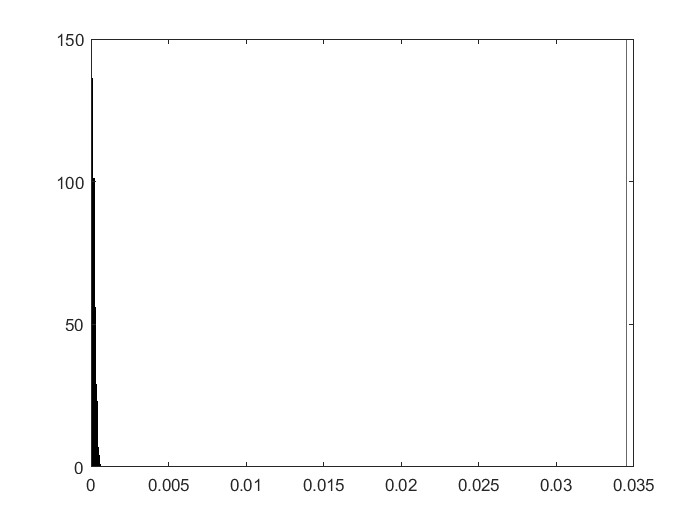

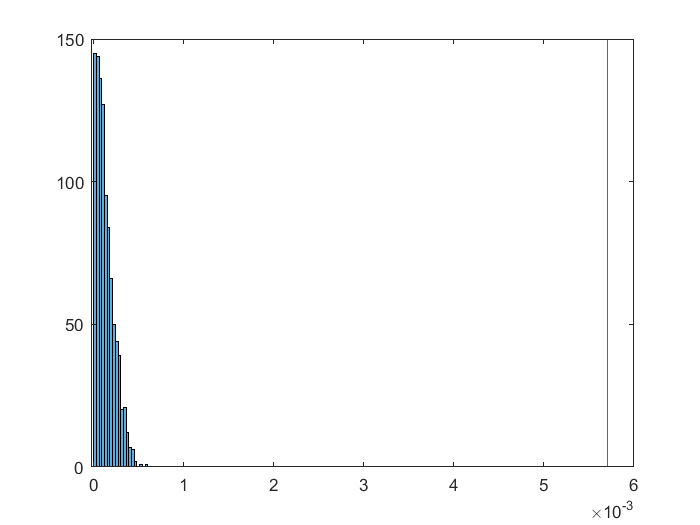

%uso funzione my_permutation_test() 



piccolo=zeros(length(cell2mat(norm(1:4,1)))+length(cell2mat(norm(1:4,2)))+length(cell2mat(norm(1:4,3))),2);
grande=zeros(length(cell2mat(norm(5:8,1)))+length(cell2mat(norm(5:8,2)))+length(cell2mat(norm(5:8,3))),2);
index_p=cumsum ([1, length(cell2mat(norm(1:4,1))), length(cell2mat(norm(1:4,2))), length(cell2mat(norm(1:4,3)))]) ;
index_g=cumsum ([1, length(cell2mat(norm(5:8,1))), length(cell2mat(norm(5:8,2))), length(cell2mat(norm(5:8,3)))]) ;

lento=zeros(length(cell2mat(norm([1,2,5,6],1)))+length(cell2mat(norm([1,2,5,6],2)))+length(cell2mat(norm([1,2,5,6],3))),2);
veloce=zeros(length(cell2mat(norm([3,4,7,8],1)))+length(cell2mat(norm([3,4,7,8],2)))+length(cell2mat(norm([3,4,7,8],3))),2);
index_l=cumsum ([1, length(cell2mat(norm([1,2,5,6],1))), length(cell2mat(norm([1,2,5,6],2))), length(cell2mat(norm([1,2,5,6],3)))]) ;
index_v=cumsum ([1, length(cell2mat(norm([3,4,7,8],1))), length(cell2mat(norm([3,4,7,8],2))), length(cell2mat(norm([3,4,7,8],3)))]) ;


for index_sogg=1:num_soggetti
       
    piccolo(index_p(index_sogg):index_p(index_sogg+1)-1,:)=cell2mat(norm(1:4,index_sogg));
    grande(index_g(index_sogg):index_g(index_sogg+1)-1,:)=cell2mat(norm(5:8,index_sogg));
    
    lento(index_l(index_sogg):index_l(index_sogg+1)-1,:)=cell2mat(norm([1,2,5,6],index_sogg));
    veloce(index_v(index_sogg):index_v(index_sogg+1)-1,:)=cell2mat(norm([3,4,7,8],index_sogg));
      
end


p_value_GvsP = my_permutation_test(piccolo', grande', 1000);

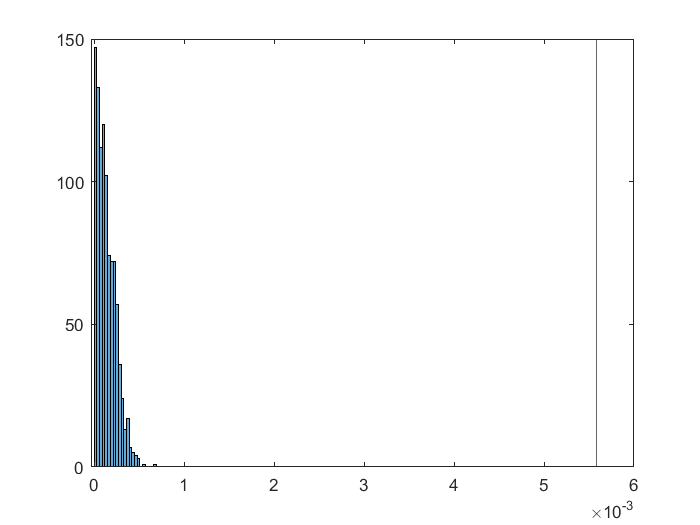

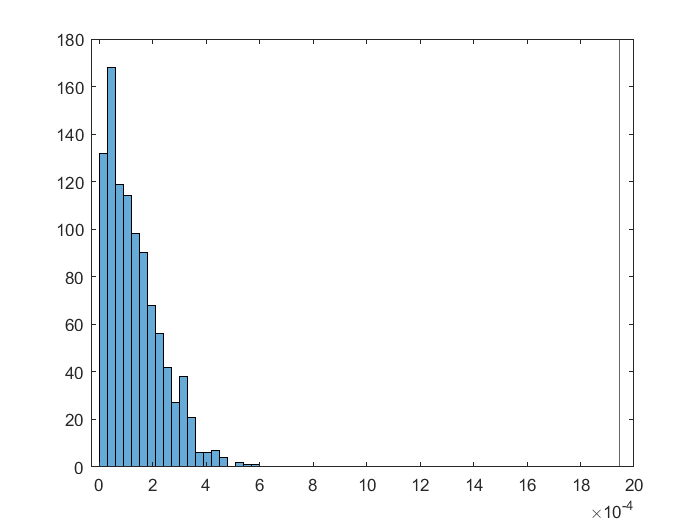

p_ value_LvsV= my_permutation_test(lento', veloce', 1000);